## PD control of an electric machinery

## Initialization

clc
clear
close all
Dimension=1;
tol=0.2;
maximum_entropy=400;
Duration=500;
timetic=3;
load MaglevNetwork.mat
load training_data.mat
xInterval = [1.5 2.5];
uInterval = [0 1];

## 1.Getting trajectories based on random initial conditions

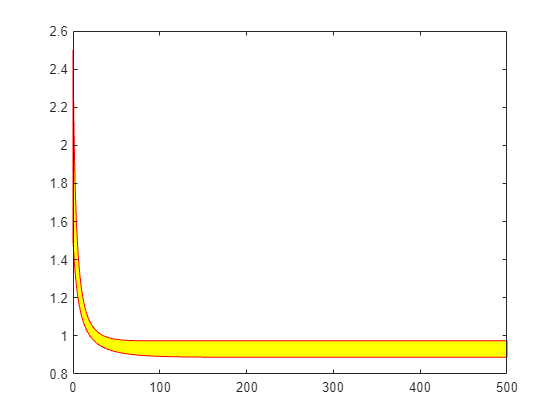

inputInterval = [xInterval; uInterval];
activeFcn = network.activeType;
W = network.weight;
b = network.bias;
ffnn = ffnetwork(W,b,activeFcn);
generateFcn(ffnn);
color='r';
% Reachable set computation
x = [uInterval;xInterval];
y = xInterval;
for k = 0:1:Duration
    outputIntvl_array{k+1} = y;
    %[y,~] = outputSetUniform(ffnn,x,tol);
    [y,~] = outputSetUniform(ffnn,x,0.1);
    y = intervalCompute.boundInterval(y);
    x = [uInterval;y];
end
intervalCompute.plotPipe(0:Duration,outputIntvl_array,1,'y',color)

## 2.Learning the system based on the state samples

% [Pn_train,inputps] = mapminmax(x_in);
% [Tn_train,outputps] = mapminmax(x_out);


lowerbound= min(xs(:,1));
upperbound= max(xs(:,2));
init_interval{1}=[lowerbound,upperbound]; % localized boundary

% a. Data-driven Partitioning
P=partitions(init_interval,xs,t);
intervals=ME(P,tol,maximum_entropy,Dimension);

Starting Maximum Entropy Partitioning with epsilon=400
Number of Partitions 1
历时 0.029295 秒。
Number of Partitions 2
历时 0.017969 秒。
Number of Partitions 2
历时 0.017415 秒。
Number of Partitions 3
历时 0.012172 秒。
Number of Partitions 3
历时 0.012576 秒。
Number of Partitions 3
历时 0.020755 秒。
Number of Partitions 4
历时 0.016043 秒。
Number of Partitions 5
历时 0.012087 秒。
Number of Partitions 6
历时 0.010809 秒。
Number of Partitions 6
历时 0.014477 秒。
Number of Partitions 7
历时 0.012649 秒。
Number of Partitions 8
历时 0.010633 秒。
Number of Partitions 8
历时 0.015533 秒。
Number of Partitions 9
历时 0.013355 秒。
Number of Partitions 10
历时 0.011834 秒。
Number of Partitions 11
历时 0.010522 秒。
Number of Partitions 11
历时 0.015615 秒。
Number of Partitions 12
历时 0.012788 秒。
Number of Partitions 13
历时 0.011467 秒。
Number of Partitions 13
历时 0.011574 秒。
Number of Partitions 13
历时 0.012290 秒。
Number of Partitions 14
历时 0.011034 秒。
Number of Partitions 14
历时 0.012178 秒。
Number of Partitions 15
历时 0.000256 秒。
Number of Partitions 15

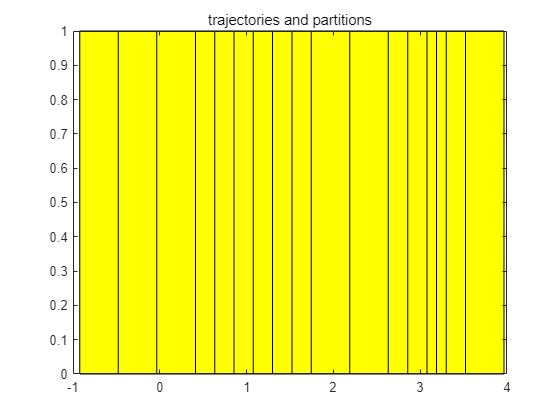

P.intervals=intervals;


figure
%plot(Pn_train(1,:),Pn_train(2,:),'r','LineWidth',1)
for i = 1:size(P.intervals,2)
    %plot([i i],P.intervals{i},'LineWidth',2,'MarkerEdgeColor','k');
    x=[P.intervals{i},P.intervals{i}(2),P.intervals{i}(1)];
    y=[0 0 1 1];
    fill(x,y,'y')
    hold on
end
title('trajectories and partitions')

## Relationship of different partitions

1.For reachable set computation (mapminmax linear transformation)

%figure
IntersectSet= zeros(size(intervals,2));
for i = 1: size(intervals,2)
    x = [uInterval;intervals{i}];
    [NextSetOutput,~] = outputSetUniform(ffnn,x,0.1);
    NextSetInput=intervalCompute.boundInterval(NextSetOutput);
    % NextSetInput=ELMreachabilitynnv(intervals{i},ELM);
    for j = 1: size(intervals,2)
        I=intervals{j};
        if(I(1) < NextSetInput(2) && NextSetInput(1) < I(2))
            IntersectSet(i,j)=1;
        end
    end
    %  hold on
    NextSetInput=[];
    NextSetOutput=[];
end

## Generate an abstract graph then save it in .xml

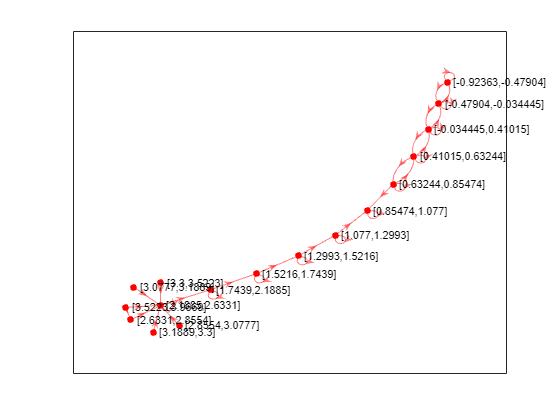

Num=ceil(sqrt(size(IntersectSet,1)));
% 1.Compute Each position in Graph
relativeRate=2400/size(IntersectSet,1);
k=1;
for i = 1:Num
    for j =1:Num
        Location{k}=strcat(['x="',num2str(i*relativeRate+5)],['" y="',num2str(j*relativeRate+5),'"']);
        point{k}{1}=[num2str(i*relativeRate+5)];
        point{k}{2}=[num2str(j*relativeRate+5)];
        k=k+1;
    end
end
% 2.Add node name
for i = 1:size(IntersectSet,1)
    b=strcat(['location id= id',num2str(i-1)],[' ',Location{i}]);
    LocationInfo{i}= replace(b,"''",'"');
    points{i}=point{i};
    %nodename{i}=strcat(['id',num2str(i-1)]);
    nodename{i}=strcat(['[',num2str(P.intervals{i}(1)),',',num2str(P.intervals{i}(2)),']']);
    %nodename{i}=LocationInfo{i};
end
% 2.
ModelGraph=digraph(IntersectSet,nodename);
figure
plot(ModelGraph,'r')


% Finding cycles in group
% cycles = allcycles(ModelGraph,'MaxCycleLength',4,'MinCycleLength',2)

% S = struct(ModelGraph);

import matlab.io.xml.dom.*
docNode = Document("nta");
docRootNode = getDocumentElement(docNode);


declartion = createElement(docNode,"declaration");
appendChild(declartion,createTextNode(docNode,sprintf('// Place global declarations here.\nclock x;')));

templateElement = createElement(docNode,"template");
name = createElement(docNode,"name");
name.setAttribute('x','5');
name.setAttribute('y','5');
appendChild(name,createTextNode(docNode,"Template"));
appendChild(templateElement,name);
%appendChild(declartion,'');
for i=1:size(IntersectSet,1)
    location = createElement(docNode,'location');
    location.setAttribute('id',strcat(['id',num2str(i-1)]));
    location.setAttribute('x',points{i}{1});
    location.setAttribute('y',points{i}{2});
    name = createElement(docNode,'name');
    name.setAttribute('x',num2str(str2num(points{i}{1})+17));
    name.setAttribute('y',num2str(str2num(points{i}{2})-25));
    appendChild(name,createTextNode(docNode,strcat(['id',num2str(i-1)])));
    
    label = createElement(docNode,'label');
    label.setAttribute('kind',"invariant");
    label.setAttribute('x',num2str(str2num(points{i}{1})+1));
    label.setAttribute('y',num2str(str2num(points{i}{2})+15));
    appendChild(label,createTextNode(docNode,strcat(['x<=',num2str(timetic)])));
    
    appendChild(location,name);
    appendChild(location,label);
    % if (i==1)
    %initial = createElement(docNode,'Initial');
    %appendChild(location,initial);
    %end
    appendChild(templateElement,location);
end
initial = createElement(docNode,'init');
initial.setAttribute('ref',['id','0']);
appendChild(templateElement,initial);

% Generate Transition based on locations

% for i = 1: size(ModelGraph.Edges,1)
%     transition = createElement(docNode,'transition');
%     source=createElement(docNode,'source');
%     source.setAttribute('ref',ModelGraph.Edges.EndNodes{i,1});
%     target=createElement(docNode,'target');
%     target.setAttribute('ref',ModelGraph.Edges.EndNodes{i,2});
% 
%     label = createElement(docNode,'label');
%     label.setAttribute('kind',"assignment");
%     appendChild(label,createTextNode(docNode,"x:=0"));
% 
%     %name = createElement(docNode,'name');
%     %appendChild(name,createTextNode(docNode,strcat(['transition ',num2str(i)])));
%     %appendChild(transition,name);
% 
%     appendChild(transition,source);
%     appendChild(transition,target);
%     appendChild(transition,label);
%     appendChild(templateElement,transition);
% end

% Generate Transition based on State Labels

for i =1:size(IntersectSet,1)
    for j = 1:size(IntersectSet,2)
    if (IntersectSet(i,j)==1)
    transition = createElement(docNode,'transition');
     source=createElement(docNode,'source');
     source.setAttribute('ref',strcat(['id',num2str(i-1)]));
     target=createElement(docNode,'target');
     target.setAttribute('ref',strcat(['id',num2str(j-1)]));
     label = createElement(docNode,'label');
     label.setAttribute('kind',"assignment");
     appendChild(label,createTextNode(docNode,"x:=0"));
     appendChild(transition,source);
     appendChild(transition,target);
     appendChild(transition,label);
     appendChild(templateElement,transition);
    end
    end
end

appendChild(docRootNode,declartion);
appendChild(docRootNode,templateElement);

system = createElement(docNode,"system");
appendChild(system,createTextNode(docNode,sprintf('// Place template instantiations here.\nP1 = Template();  \n// List one or more processes to be composed into a system.\nsystem P1;')));
appendChild(docRootNode,system);

queries = createElement(docNode,"queries");
query = createElement(docNode,"query");

formula=createElement(docNode,"formula");
appendChild(formula,createTextNode(docNode,"E<>P1.id0"));
appendChild(query,formula);

comment=createElement(docNode,"comment");
appendChild(comment,createTextNode(docNode,"can the model check tool work?"));
appendChild(query,comment);

query1=createElement(docNode,"query");
formula1=createElement(docNode,"formula");
appendChild(formula1,createTextNode(docNode,"A<>(P1.id11 or P1.id13 or P1.id6 or P1.id18 or P1.id19 or P1.id12 or P1.id27 or P1.id28 or P1.id20 )"));
appendChild(query1,formula1);

comment1=createElement(docNode,"comment");
appendChild(comment1,createTextNode(docNode,"Is it stable?"));

appendChild(query1,comment1);


appendChild(queries,query);
appendChild(queries,query1);
appendChild(docRootNode,queries);



xmlFileName = "MaglevModelGraph1.xml";
writer = matlab.io.xml.dom.DOMWriter;
writer.Configuration.FormatPrettyPrint = true;
writeToFile(writer,docNode,xmlFileName);

